## Q2

Data for each frequencies are saved in freq_data_{d}.mat file, where d is integer value representing index of frequency in array given below.

clear all;
% freq_array = [0.5 1.0 2.0 2.5 3.0 3.5 ...
%         4.0 4.5 5.0 8.0 12.00 16.0 20.0 30.0];

freq_array = logspace(0,1.6,20);

w_arr = 2*pi*freq_array;

Us = zeros(length(freq_array),1);
Phis = zeros(length(freq_array),1);
M = zeros(length(freq_array),1);

disp ("Running data cleaning")

Running data cleaning


for i = 1:length(freq_array)
    fileName = sprintf("freq_data_%d.mat",i);
    disp("Reading file ...")
    load(fileName)
    figure()
    
    % -- Seperating time, input and output values
    f = freq_array(i);

    t = data(1,:)';
    u = data(2,:)';
    v = data(4,:)';

    % -- Masking and removing first 5 second of transient data

    t_mask = t >= 5;

    t = t(t_mask);
    u = u(t_mask);
    v = v(t_mask);

    med_filter_v = medfilt1(v,4);
    v = med_filter_v;
    
    fprintf("Interpolating data for %d",f)
    data = interpolateSineData(t,v,f);
    
    % -- Storing data for different frequencies 
    fprintf("Storing data for %d",f)
    Us(i) = data.U;
    Phis(i) = data.Phi;
    M(i) = data.M;
end

Reading file ...


Interpolating data for 1

Storing data for 1

Reading file ...


Interpolating data for 1.213977e+00

Storing data for 1.213977e+00

Reading file ...


Interpolating data for 1.473741e+00

Storing data for 1.473741e+00

Reading file ...


Interpolating data for 1.789087e+00

Storing data for 1.789087e+00

Reading file ...


Interpolating data for 2.171911e+00

Storing data for 2.171911e+00

Reading file ...


Interpolating data for 2.636651e+00

Storing data for 2.636651e+00

Reading file ...


Interpolating data for 3.200834e+00

Storing data for 3.200834e+00

Reading file ...


Interpolating data for 3.885740e+00

Storing data for 3.885740e+00

Reading file ...


Interpolating data for 4.717199e+00

Storing data for 4.717199e+00

Reading file ...


Interpolating data for 5.726572e+00

Storing data for 5.726572e+00

Reading file ...


Interpolating data for 6.951928e+00

Storing data for 6.951928e+00

Reading file ...


Interpolating data for 8.439482e+00

Storing data for 8.439482e+00

Reading file ...


Interpolating data for 1.024534e+01

Storing data for 1.024534e+01

Reading file ...


Interpolating data for 1.243761e+01

Storing data for 1.243761e+01

Reading file ...


Interpolating data for 1.509897e+01

Storing data for 1.509897e+01

Reading file ...


Interpolating data for 1.832981e+01

Storing data for 1.832981e+01

Reading file ...


Interpolating data for 2.225197e+01

Storing data for 2.225197e+01

Reading file ...


Interpolating data for 2.701338e+01

Storing data for 2.701338e+01

Reading file ...


Interpolating data for 3.279363e+01

Storing data for 3.279363e+01

Reading file ...


Interpolating data for 3.981072e+01

Storing data for 3.981072e+01

disp("Finished cleaning");

Finished cleaning


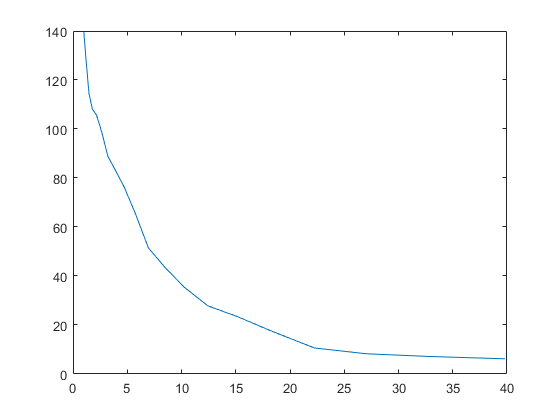

plot(freq_array,Us)

## Testing plot for predicted and the measured value

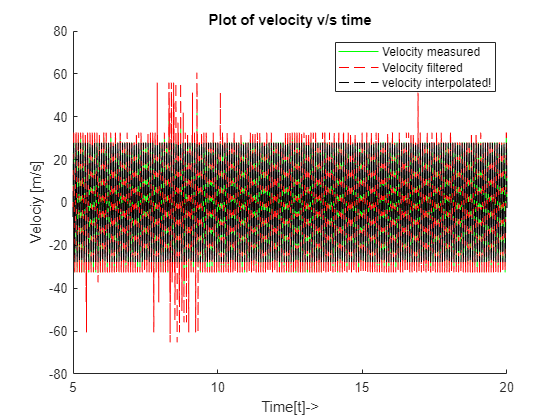

test_index = 14;
fileName = sprintf("freq_data_%d.mat",test_index);

f = freq_array(test_index);
%-- Input datas 
load(fileName);
% -- loading data from the system
t = data(1,:)';
u = data(2,:)';
v = data(4,:)';

t_mask = t >= 5;

t = t(t_mask);
u = u(t_mask);
v = v(t_mask);

%-- Filtered velocity
med_filter_v =  medfilt1(v,4);
% -- Interpolated parameters
U_i = Us(test_index); Phi_i = Phis(test_index);
M_i = M(test_index);
w = 2*pi*f;
interpolatedSine = U_i*sin(w*t + Phi_i) + M_i;

figure();
hold on;
plot(t,med_filter_v,'g')
plot(t,v,'r--');
plot(t,interpolatedSine,'k--')
xlabel("Time[t]->")
ylabel("Velociy [m/s]")
title("Plot of velocity v/s time")
legend("Velocity measured","Velocity filtered","velocity interpolated!")
hold off;

#### Parameters from question 1

#### Calculating response for system

#### Update m and b based upon measure gain and phase

## --


$$|G(jw)| = \frac{2 K} {\sqrt{ (\tau \omega)^2 + 1}}$$
 

K = 1/b 


$$\tau = \frac{m}{b}$$


Phase(G(jw)) = $atan2(-\tau \omega,1)
$


m_c = 8.61e-04;
b_c = 0.0067;
dc_p = 0.4521;
dc_m = -0.3354;

K_c = 1/b_c;
tau_c = m_c/b_c;
w = linspace(0,150,4000);
G_jw_c = 2*K_c./sqrt((tau_c*w).^2+1);
phi_c = atan2(-tau_c*w,1);

m_nc = 9.28e-04;
b_nc = 0.0087;

% -- without coloumb
K_nc = 1/b_nc;
tau_nc = m_nc/b_nc;
G_jw_nc = 2*K_nc./sqrt((tau_nc*w).^2+1);
phi_nc = atan2(-tau_nc*w,1);

### Fitting the measured value to gain and phase curve

% -- x = [k, tau] -> Decision variable

Gain = @(x) 2*x(1)./sqrt((x(2)*w_arr).^2 + 1); % |G (jw) | 
Gain_obj = @(x) norm(Us - Gain(x));
Phase = @(x) atan2(-x(2)*w_arr,1)

Phase = function_handle with value:
    @(x)atan2(-x(2)*w_arr,1)


Phase_obj = @(x) norm(Phis - Phase(x));
weight_gain = 0.65;
weight_phase = 1 - weight_gain;
obj = @(x) weight_gain*Gain_obj(x) + weight_phase*Phase_obj(x);
x0 = [K_nc tau_nc]

x0 =   114.9425    0.1067


Using non linear optimization to fit the gain and phase values!!!

params_up = fmincon(obj,[K_nc tau_nc]);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


K_up = params_up(1); tau_up = params_up(2);

% -- Calculating response for tuned parameters
G_jw_up = 2*K_up./sqrt((tau_up*w).^2 + 1);
phi_up = atan2(-tau_up*w,1)

phi_up =          0   -0.0025   -0.0049   -0.0074   -0.0099   -0.0124   -0.0148   -0.0173   -0.0198   -0.0222   -0.0247   -0.0272   -0.0296   -0.0321   -0.0346   -0.0370   -0.0395   -0.0420   -0.0444   -0.0469   -0.0494   -0.0518   -0.0543   -0.0568   -0.0592   -0.0617   -0.0642   -0.0666   -0.0691   -0.0715   -0.0740   -0.0764   -0.0789   -0.0814   -0.0838   -0.0863   -0.0887   -0.0912   -0.0936   -0.0961   -0.0985   -0.1010   -0.1034   -0.1058   -0.1083   -0.1107   -0.1132   -0.1156   -0.1180   -0.1205


## Plotting systems measured response and it's gain and phase response according to bode plot

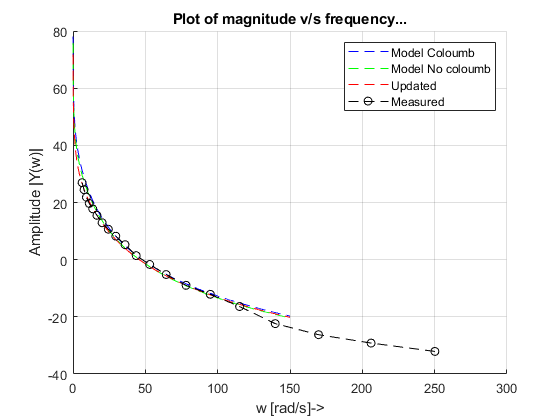

figure ();
hold on;

title("Plot of magnitude v/s frequency...");
xlabel("w [rad/s]->");
ylabel("Amplitude |Y(w)|")
%w = logspace(-3,3,3000);








semilogx(w',20*log10(G_jw_c)-20*log10(w),'b--')
semilogx(w',20*log10(G_jw_nc)-20*log10(w),'g--')
semilogx(w',20*log10(G_jw_up)-20*log10(w),'r--')


semilogx(w_arr,20*log10(Us)-20*log10(w_arr'),'ok--');
grid on;
legend("Model Coloumb","Model No coloumb","Updated","Measured")

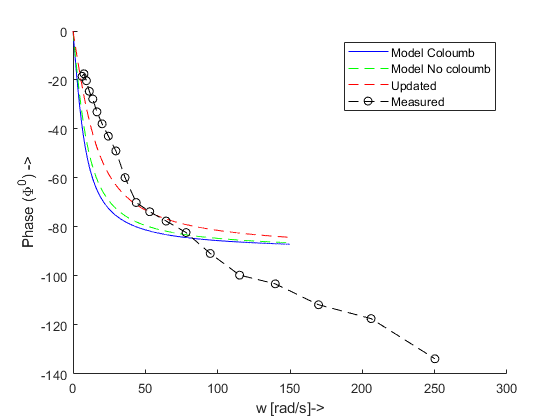


figure();
hold on;

plot(w,rad2deg(phi_c),'b');
plot(w,rad2deg(phi_nc),'g--');
plot(w,rad2deg(phi_up),'r--')

plot(w_arr,rad2deg(Phis),'ok--');

xlabel("w [rad/s]->");
ylabel("Phase (\Phi^0) ->")
legend("Model Coloumb","Model No coloumb","Updated","Measured")

### Parameters from bode plot

disp("Parameters from bode plot include:")

Parameters from bode plot include:


b_up = 1/K_up

b_up = 0.0137

m_up = tau_up*b_up

m_up = 9.0411e-04